# Diseño de un observador de orden completo

### (Ejemplo  10 -7: Ingeniería de Control moderna Pagina 762)

Se desea diseñar un observador de estados de orden completo

Se desea obtener la función de transferencia del controlador basado en un observador

Obtener la respuesta a las condiciones iniciales x0=[1;0] y e0=[0.5;0];

clear
close all
% Especificación de las condiciones iniciales de los estados y condiciones
% iniciales del error (diferencia entre los estados y los estados estimados
x0=[1;0];
e0=[0.5;0];
% Matrices del sistema
A= [0 1; 20.6 0]

A =          0    1.0000
   20.6000         0


B = [0;1]

B =      0
     1


C = [1 0]

C =      1     0


J=[-1.8+2.4*1i -1.8-2.4*1i]   % Polos deseados en lazo cerrado

J =   -1.8000 + 2.4000i  -1.8000 - 2.4000i


K=acker(A,B,J)

K =    29.6000    3.6000


L=[-8 -8] % Polos deseados del obervador

L =     -8    -8


### Cálculo de la matriz de ganancias del observador de estados de orden completo

Ke=acker(A',C',L)'

Ke =    16.0000
   84.6000


### Cálculo de las matrices del sistema en lazo cerrado

Ecuacion 10-70 texto Ogata para un sistema regulador 

%% 
AA=[A-B*K  B*K; zeros(2,2) A-Ke*C] 

AA =          0    1.0000         0         0
   -9.0000   -3.6000   29.6000    3.6000
         0         0  -16.0000    1.0000
         0         0  -64.0000         0


BB=eye(4)

BB =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CC=eye(4);
DD=eye(4);
sys = ss(AA,BB,CC,DD)

sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    -9  -3.6  29.6   3.6
   x3     0     0   -16     1
   x4     0     0   -64     0
 
  B = 
       u1  u2  u3  u4
   x1   1   0   0   0
   x2   0   1   0   0
   x3   0   0   1   0
   x4   0   0   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
Continuous-time state-space model.


#### Respuesta del sistema regulador a condiciones iniciales

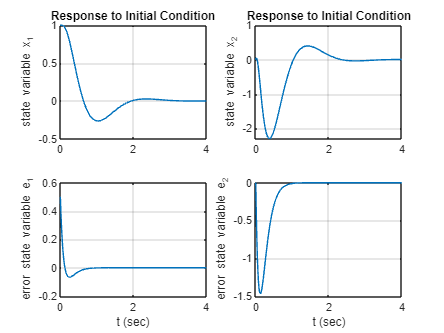

t = 0:0.01:4;
z = initial(sys,[x0;e0],t);
x1 = [1 0 0 0]*z';
x2 = [0 1 0 0]*z';
e1 = [0 0 1 0]*z';
e2 = [0 0 0 1]*z';
subplot(2,2,1)
plot(t,x1 ),grid
title('Response to Initial Condition')
ylabel('state variable x_1')
subplot(2,2,2)
plot(t,x2),grid
title('Response to Initial Condition')
ylabel('state variable x_2')
subplot(2,2,3); plot(t,e1),grid
xlabel('t (sec)'), ylabel('error state variable e_1')
subplot(2,2,4); plot(t,e2),grid
xlabel('t (sec)'), ylabel('error state variable e_2')

## Funcion de transferencia del controlador basado en un observador

Usando las Ecuaciones 10-71 y 10-72 texto Ogata

AA = A-Ke*C-B*K;  
BB = Ke;
CC = K; 
DD = 0;
[num,den] = ss2tf(AA,BB,CC,DD);
UsMinYs=tf(num,den)

UsMinYs =
 
     778.2 s + 3691
  --------------------
  s^2 + 19.6 s + 151.2
 
Continuous-time transfer function.
Model Properties


## Funcion de transferencia del controlador basado en un observador

En forma simbolica y usando la Ec. 10-73

syms s
UsMinYs1=K*inv(s*eye(size(A,1))-A+Ke*C+B*K)*Ke

$$UsMinYs1 = \frac{2368\,\left(5\,s+18\right)}{5\,\left(5\,s^{2}+98\,s+756\right)}-\frac{14436}{5\,s^{2}+98\,s+756}+\frac{7614\,\left(s+16\right)}{5\,\left(5\,s^{2}+98\,s+756\right)}$$

UsMinYs2=simplify(UsMinYs1)

$$UsMinYs2 = \frac{2\,\left(9727\,s+46134\right)}{5\,\left(5\,s^{2}+98\,s+756\right)}$$

% UsminYs2==UsMinYs. 
% Verificar dividiendo el numerador y denominador entre
% el coeficiente de s^2 del denominador pe: 5*98/25, 5*756/25
% Para el numerador: 2*9727/25 , 2*46134/25

Calculo de la ecuación característica (de la ecuación 10-70)

sImA=s*eye(size(A,1))-A;
EC=det(sImA+B*K)*det(sImA+Ke*C) 

$$EC = \left(s^{2}+\frac{18\,s}{5}+9\right)\,\left(s^{2}+16\,s+64\right)$$